首先，加载原始数据集

clc
clear
load neuralsignalAndTrajs

现在在Workspace中可以看到三个以traj开头的变量和三个以T开头的变量。traj开头的变量代表轨迹数据，T开头的变量代表神经数据。LU表示Left Up, 即左上方，表示电机控制目标物体从中间向左上方运动。RD表示Right Down，表示电机控制目标物体从中间向右下方运动。S表示Static，表示目标物体在中间静止不动

现在双击任意一个以traj开头的变量，以trajLU为例，每一行对应于一个trial，但有用的只有最后一列，perf表示去除了坏点以及进行了修补的轨迹，目前每个perf单元格只有三列数据，分别是x、y、z对应的位置，采样率是80Hz

运行下面的代码可以计算出每个时刻的速度和加速度，结果依然保存在perf的各个单元格中

% velocity and acceleration
% 1-3 position
% 4-6 velocity
% 7-9 acc
for i=1:120
    trajRD(i).perf(1,4:6)=[0 0 0];
    trajLU(i).perf(1,4:6)=[0 0 0];
    trajS(i).perf(1,4:6)=[0 0 0];
    for j=2:length(trajRD(i).perf)
        trajRD(i).perf(j,4:6)=trajRD(i).perf(j,1:3)-trajRD(i).perf(j-1,1:3);      
    end
    
    for j=2:length(trajLU(i).perf)
         trajLU(i).perf(j,4:6)=trajLU(i).perf(j,1:3)-trajLU(i).perf(j-1,1:3);
    end
    
    for j=2:length(trajS(i).perf)
        trajS(i).perf(j,4:6)=trajS(i).perf(j,1:3)-trajS(i).perf(j-1,1:3);
    end
end
% acc
for i=1:120
    trajRD(i).perf(1,7:9)=[0 0 0];
    trajLU(i).perf(1,7:9)=[0 0 0];
    trajS(i).perf(1,7:9)=[0 0 0];

    trajRD(i).perf(2,7:9)=[0 0 0];
    trajLU(i).perf(2,7:9)=[0 0 0];
    trajS(i).perf(2,7:9)=[0 0 0];

    for j=3:length(trajRD(i).perf)
        trajRD(i).perf(j,7:9)=trajRD(i).perf(j,4:6)-trajRD(i).perf(j-1,4:6);      
    end
    
    for j=3:length(trajLU(i).perf)
         trajLU(i).perf(j,7:9)=trajLU(i).perf(j,4:6)-trajLU(i).perf(j-1,4:6);
    end
    
    for j=3:length(trajS(i).perf)
        trajS(i).perf(j,7:9)=trajS(i).perf(j,4:6)-trajS(i).perf(j-1,4:6);
    end
end

此时再双击任意一个traj变量，可以看到每一个perf单元格内变成了9列，前三列是位置，中间三列是速度，末尾三列是加速度

运行以下代码，对神经信号进行平滑处理，本质上是用一个sd为0.0125的高斯核函数与数据进行卷积，此处未进行降采样，所以采样率依然是80Hz，即每个bin的宽度是0.0125s。实际上，可以考虑降采样到40Hz或20Hz，即bin宽调整为0.025s或0.05s，相应的，高斯核函数的sd也要调整为大于等于0.025或0.05的值。另外，这里只选用了前120个trial，由变量Trial指定

%% RD
Trial=120;
for i=1:Trial
    tLen=length(trajRD(i).perf);
    for k=1:9
        for j=1:tLen
            temp(1,j)=trajRD(i).perf(j,k);
        end
        xRD{i,1}(k,:)=transpose(smooth(temp,6));
        clear temp
    end
end 

N=length(TRD{1, 1}.neurons);
bin=0.0125;

sigma =0.05; %Standard deviation of the kernel 5 15 ms
edges=[-3*sigma:0.0125:3*sigma]; %Time ranges form -3*st. dev. to 3*st. dev.
kernel = normpdf(edges,0,sigma); %Evaluate the Gaussian kernel
kernel = kernel*0.0125; %Multiply by bin width so the probabilities sum to 1

%求bin后的spike数目，并进行卷积
for i=1:Trial
    tLen=length(trajRD(i).perf);
    for j=1:N
        s=TRD{i,1}.CenterHit;
        for k=1:tLen
            e=s+bin;
            temp2=find(TRD{i,1}.neurons{j,2}(:)>s & TRD{i,1}.neurons{j,2}(:)<e);
            temp3(k)=length(temp2);%xRD{i,2}(j,k)=length(temp2);
            s=e;
        end
        temp4=conv(temp3,kernel); %Convolve spike data with the kernel
        center = ceil(length(edges)/2); %Find the index of the kernel center
        xRD{i,2}(j,:)=temp4(center:tLen+center-1); %Trim out the relevant portion of the spike density
    end
end

%% LU
Trial=120;
for i=1:Trial
    tLen=length(trajLU(i).perf);
    for k=1:9
        for j=1:tLen
            temp(1,j)=trajLU(i).perf(j,k);
        end
        xLU{i,1}(k,:)=transpose(smooth(temp,6));
        clear temp
    end
end 

N=length(TLU{1, 1}.neurons);
bin=0.0125;


%求bin后的spike数目，并进行卷积
for i=1:Trial
    tLen=length(trajLU(i).perf);
    for j=1:N
        s=TLU{i,1}.CenterHit;
        for k=1:tLen
            e=s+bin;
            temp2=find(TLU{i,1}.neurons{j,2}(:)>s & TLU{i,1}.neurons{j,2}(:)<e);
            temp3(k)=length(temp2);%xLU{i,2}(j,k)=length(temp2);
            s=e;
        end
        temp4=conv(temp3,kernel); %Convolve spike data with the kernel
        center = ceil(length(edges)/2); %Find the index of the kernel center
        xLU{i,2}(j,:)=temp4(center:tLen+center-1); %Trim out the relevant portion of the spike density
    end
end

%% Static
Trial=120;
for i=1:Trial
    tLen=length(trajS(i).perf);
    for k=1:9
        for j=1:tLen
            temp(1,j)=trajS(i).perf(j,k);
        end
        xS{i,1}(k,:)=transpose(smooth(temp,6));
        clear temp
    end
end 

N=length(TStill{1, 1}.neurons);
bin=0.0125;

%求bin后的spike数目，并进行卷积
for i=1:Trial
    tLen=length(trajS(i).perf);
    for j=1:N
        s=TStill{i,1}.CenterHit;
        for k=1:tLen
            e=s+bin;
            temp2=find(TStill{i,1}.neurons{j,2}(:)>s & TStill{i,1}.neurons{j,2}(:)<e);
            temp3(k)=length(temp2);%xS{i,2}(j,k)=length(temp2);
            s=e;
        end
        temp4=conv(temp3,kernel); %Convolve spike data with the kernel
        center = ceil(length(edges)/2); %Find the index of the kernel center
        xS{i,2}(j,:)=temp4(center:tLen+center-1); %Trim out the relevant portion of the spike density
    end
end

# ***************

# ***************

运行完以上代码后，可以看到工作空间中出现了以x开头的三个变量，将轨迹数据和神经数据组合到了一个结构体当中，以xLU为例，xLU中，每一行属于一个trial，没有包含所有trial，只选取了前120个，所以总共有120行。第一列是轨迹数据，第二列是神经数据，列数与轨迹数据相同，行数为神经元个数，这个文件里sorting出了129个神经元

运行下面的代码可以将复杂的表格中的数据重新组合，从而形成可以直接调用的训练数据集和测试数据集。在此把每个trial的数据堆叠到了一起

%% LU
trainX1=xLU{1,1}(:,:);
trainY1=xLU{1,2}(:,:);

for i=2:50
    trainX1=[trainX1 xLU{i,1}(:,:)];
    trainY1=[trainY1 xLU{i,2}(:,:)];
end

testX1=xLU{51,1}(:,:);
testY1=xLU{51,2}(:,:);

for i=52:100
    testX1=[testX1 xLU{i,1}(:,:)];
    testY1=[testY1 xLU{i,2}(:,:)];
end

%% RD
trainX2=xRD{1,1}(:,:);
trainY2=xRD{1,2}(:,:);

for i=2:50
    trainX2=[trainX2 xRD{i,1}(:,:)];
    trainY2=[trainY2 xRD{i,2}(:,:)];
end

testX2=xRD{51,1}(:,:);
testY2=xRD{51,2}(:,:);

for i=52:100
    testX2=[testX2 xRD{i,1}(:,:)];
    testY2=[testY2 xRD{i,2}(:,:)];
end

%% S
trainX3=xS{1,1}(:,:);
trainY3=xS{1,2}(:,:);

for i=2:50
    trainX3=[trainX3 xS{i,1}(:,:)];
    trainY3=[trainY3 xS{i,2}(:,:)];
end

testX3=xS{51,1}(:,:);
testY3=xS{51,2}(:,:);

for i=52:100
    testX3=[testX3 xS{i,1}(:,:)];
    testY3=[testY3 xS{i,2}(:,:)];
end

此时工作空间中有trainX1,trainY1, testX1, testY1等变量。“1”对应于LU，“2”对应于RD，“3”对应于S，train和test分别为训练数据和测试数据，X为运动轨迹、速度及加速度，Y为神经数据

运行以下代码可从训练数据集中拟合出卡尔曼滤波器的四个关键参数：A, H, W, Q，函数fitForFilter中包含了具体算法。由于加速度一般都不能被很好地预测，所以在这里只用到了三列位置、三列速度数据，故A矩阵和H矩阵大小均为6*6（6行6列）。这里以trainX1和trainY1为例，其余以此类推

clear A H W Q
neurons=[1:1:30 100:1:129];%此处指定用哪些神经元进行轨迹预测，只选用30个M1的神经元和30个PPC的神经元
neurons=neurons';
[A,W,H,Q]=fitForFilter(trainX1,trainY1,neurons);

运行下列代码可使用拟合好的卡尔曼滤波器对测试数据进行测试，这里只展示testY1和testX1对应的部分，预测结果命名为变量xr1

%% test Data
T=size(testX1,2);
Xt1=[testX1(1:6,:)];%;ones(1,T)];
Yt1=testY1(neurons,:);
[D,T]=size(Xt1);
%%
initX=Xt1(:,1);
initP = eye(D);

xp=initX;
Pp=initP;

xr1=zeros(D,T);

for i=1:T
   [xp,Pp,Kk,Pk_]=filterForHand(xp,Pp,Yt1(:,i),A,H,W,Q);
   xr1(:,i)=xp;
end

变量xr1即预测出的结果，评价结果的好坏时，应该将xr1的每一行与testX1的每一行进行比较

在这里计算测试数据集上预测值与真实值的之间的相关系数

%% performance
for i=1:D
    cc(i)=CalCC(Xt1(i,:),xr1(i,:));
    disp(cc(i))
end

    0.7709

    0.8528

    0.9259

    0.7140

    0.6172

    0.7071



这里可以直观地对预测结果和真实值进行画图比较，红色虚线是预测值，黑色实线为真实值。需要注意的是在前面形成训练数据集和测试数据集的部分（两排橙色星号标记的部分），我把所有trial的数据堆叠在了一起，这样便于计算，但不便于画图，因为画图的时候我们希望能够逐个trial地画图展示结果，所以要根据各个trial的长度计算出那一部分数据在xr1和testX中对应的位置，需要编写一个查找用的函数。在此我仅绘制出测试数据集中的第一个trial，即所有xLU数据中的第52个trial

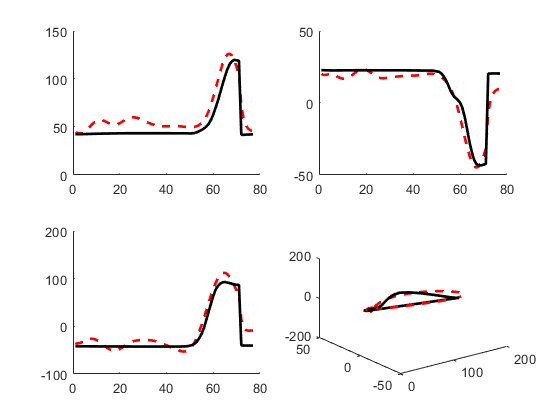

plotV=[1:77];%绘制序号
subplot(221)
hold on
plot(xr1(1,plotV),'r--','LineWidth',2);
plot(Xt1(1,plotV),'k-','LineWidth',2);
subplot(222)
hold on
plot(xr1(2,plotV),'r--','LineWidth',2);
plot(Xt1(2,plotV),'k-','LineWidth',2);
subplot(223)
hold on
plot(xr1(3,plotV),'r--','LineWidth',2);
plot(Xt1(3,plotV),'k-','LineWidth',2);
subplot(224)
hold on
view(3)
plot3(xr1(1,plotV),xr1(2,plotV),xr1(3,plotV),'r--','LineWidth',2);
plot3(Xt1(1,plotV),Xt1(2,plotV),Xt1(3,plotV),'k-','LineWidth',2);